### Pendolo inverso 

Consideriamo il modello matematico di un pendolo inverso:


$$\begin{cases}
\dot{x}_1 =x_2 \\
\dot{x}_2=-\frac{g}{L}sin(x_1(t))-\frac{k}{ML^2}x_2(t)+\frac{1}{ML^2}u(t)
\end{cases}$$


dove $x_1 \left(t\right)=\theta \left(t\right)\;,x_2 \left(t\right)=\dot{\;\theta \;} \left(t\right)$.

Assumendo g=9.81, M=L=k=1, il phase portrait per u=0 di tale sistema risulta:

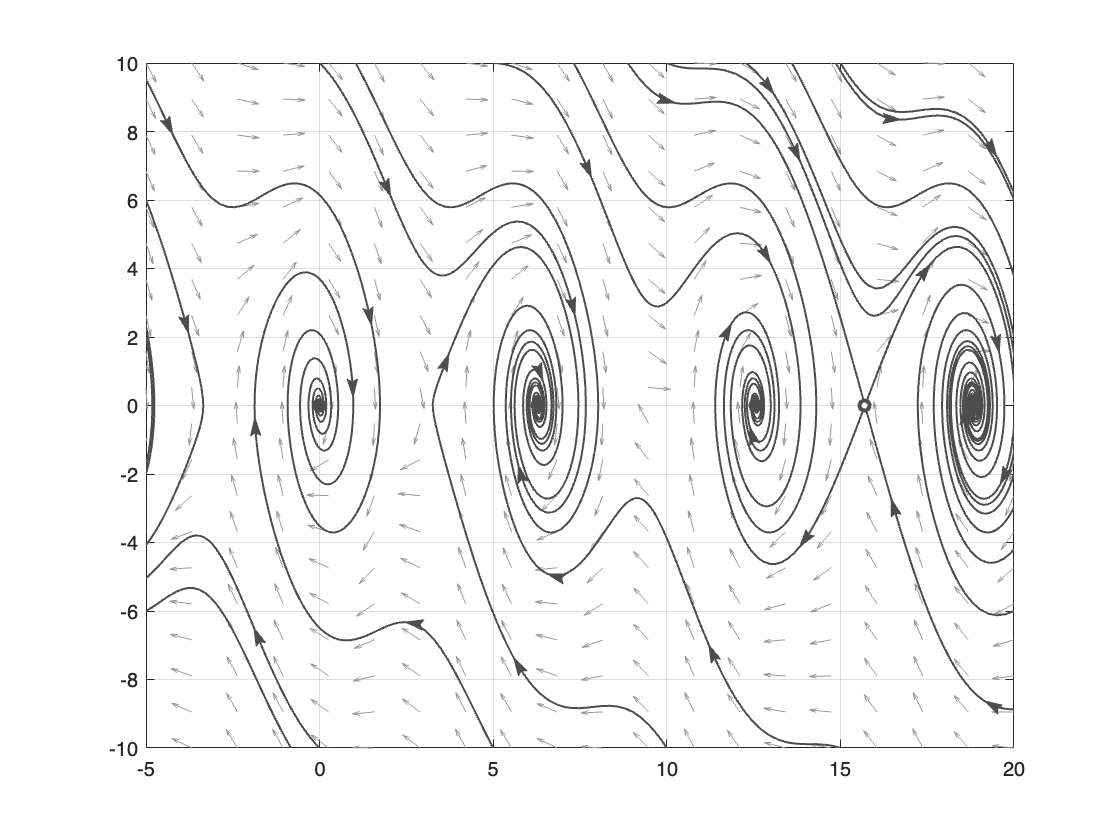

g=9.81;
M=1;
k=1;
L=1;
odefun = @(t, x) [x(2); -g/L*sin(x(1))-k/(M*L^2)*x(2)];
plotpp(odefun,'tspan', 50,...
                      'quivercolor', [0.6,0.6,0.6],...
                      'linecolor', [0.3,0.3,0.3],...
                      'xlim', [-5, 20], 'ylim', [-10, 10])

Tale sistema presenta infiniti punti di equilibrio 

 
$$\bar{\;x\;} =\left\lbrack \begin{array}{c}
k\pi \;\\
0
\end{array}\right\rbrack \;\mathrm{con}\;k=0,\pm 1,\pm 2,\;\;\ldotp \ldotp \ldotp$$


che geometricamente corrispondono alle posizioni verticale inferiore ( $x_1 =0,\pm 2\pi ,\pm 4\pi \;\ldotp \ldotp \ldotp$) e superiore del pendolo ($x_1 =\pm \pi ,\pm 3\pi \;\ldotp \ldotp \ldotp \ldotp$)

Da tale grafico risulta evidente che i punti di equilibrio verticali inferiori sono localmente asintoticamente stabili mentre quelli superiori sono localmente instabili.

Di seguito proveremo a dimostrare la stabilità di tali punti di equilibrio mediante approccio linearizzato e di Lyapunov. 

APPROCCIO BASATO SU MODELLO LINEARIZZATO

Il modello linearizzato di tale sistema presenta una matrice dinamica pari a 


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{g}{L}\cos \left(\bar{\;x_1 \;} \right) & -\frac{k}{\left(ML^{2\;} \right)}
\end{array}\right\rbrack$$


Gli autovalori di tale matrice, nel punto di equilibrio inferiore, risultano pari a 


x1_bar=0;
A=[0 1 ; -g/L*cos(x1_bar) -k/(M*L^2)];
eig(A)

ans =   -0.5000 + 3.0919i
  -0.5000 - 3.0919i


Con un phase portrait

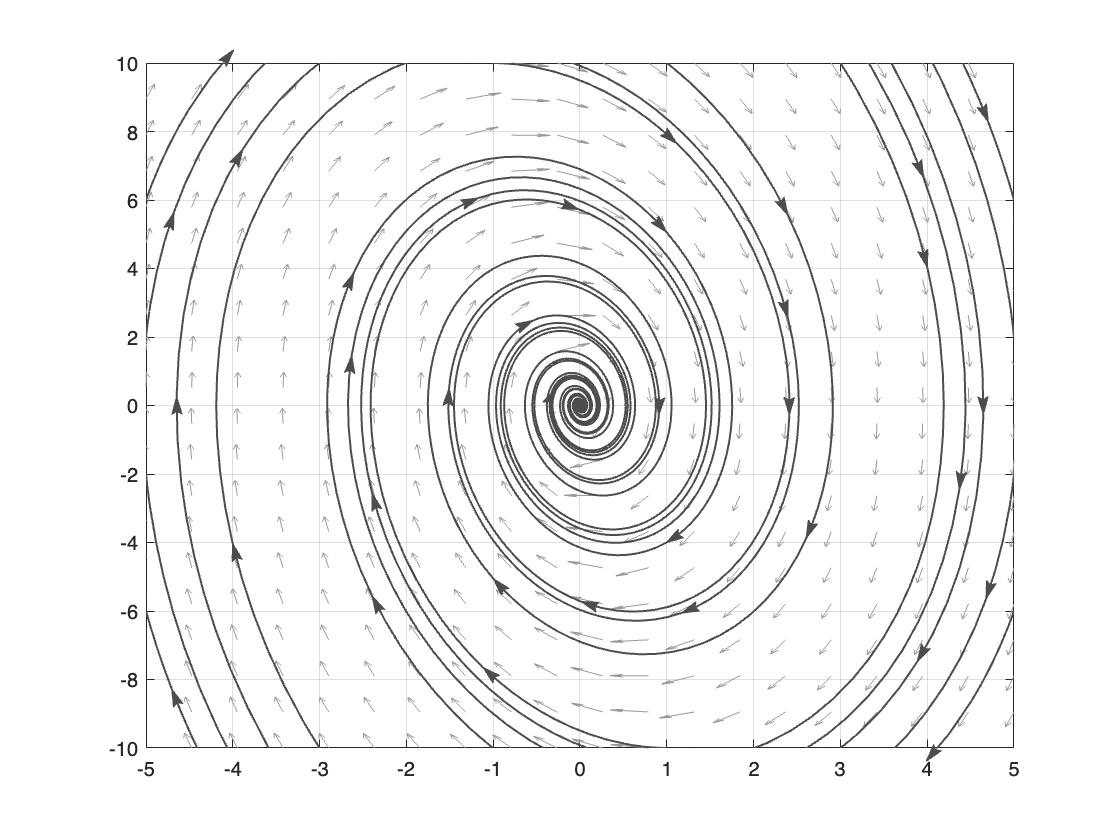


figure
odefun = @(t, x) [A(1,1)*x(1)+A(1,2)*x(2); A(2,1)*x(1)+A(2,2)*x(2)];
plotpp(odefun,'tspan', 50,...
                      'quivercolor', [0.6,0.6,0.6],...
                      'linecolor', [0.3,0.3,0.3],...
                      'xlim', [-5, 5], 'ylim', [-10, 10])

confermando che tale punto di equilibrio è localmente asintoticamente stabile.

Gli autovalori di tale matrice, nel punto di equilibrio superiore, risultano pari a 

x1_bar=pi;
A=[0 1 ; -g/L*cos(x1_bar) -k/(M*L^2)];
eig(A)

ans =     2.6718
   -3.6718


con un phase portrait

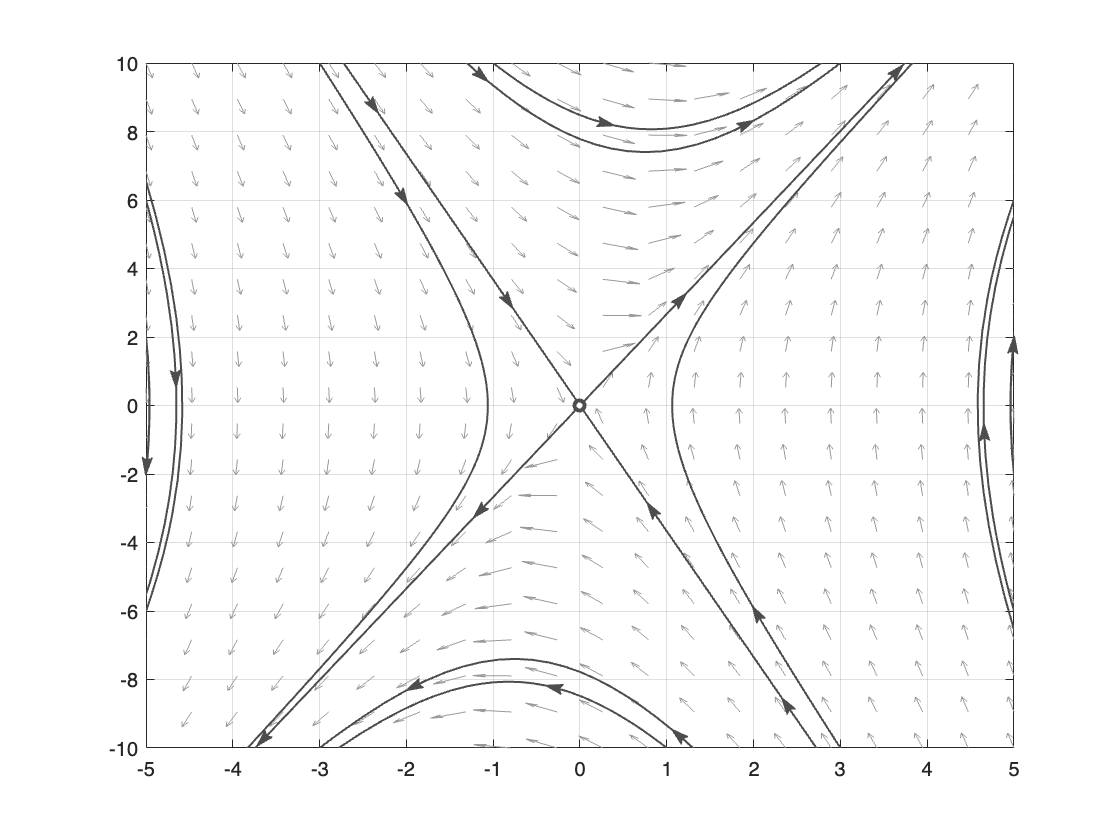


figure
odefun = @(t, x) [A(1,1)*x(1)+A(1,2)*x(2); A(2,1)*x(1)+A(2,2)*x(2)];
plotpp(odefun,'tspan', 50,...
                      'quivercolor', [0.6,0.6,0.6],...
                      'linecolor', [0.3,0.3,0.3],...
                      'xlim', [-5, 5], 'ylim', [-10, 10])

confermando la locale instabilità del punto di equilibrio.